coordinates = [8 8 8 4 2 4 6 7.5 9 12 15 16.5 18 20 2 4 6 7.5 9 12 15 16.5 18 20 4 6 7.5 9 15 16.5 18 1 3 5 7 9 12 15 16.5 18 20 3 5 7 9 15 16.5 18 20 3 5 7 9 12 15 16.5 18 20
    1 3 5 4 8 8 8 8 8 8 8 8 8 8 10 10 10 10 10 10 10 10 10 10 11 11 11 11 11 11 11 13 13 13 13 13 13.5 13 13 13 13.5 14 14 14 14 14 14 14 15 16 16 16 16 16 16 16 16 18]; %All nodes

    
types = [4 4 4 1 2 2 2 2 2 2 2 2 2 2 2 2 2 2 2 2 2 2 2 2 2 2 2 2 2 2 2 2 2 2 2 2 2 2 2 2 2 2 2 2 2 2 2 2 2 2 2 2 2 2 2 2 2 3]; % 1=depot, 2=shelf, 3=bay, 4=home_robot

EndNodes = [1 2 3 4 4 4 4 4 5 5 6 7 8 9 10 10 11 12 13 14 15 15 15 16 17 18 19 20 20 20 20 21 22 23 24 24 25 26 27 29 30 32 32 32 33 34 35 36 37 37 37 37 38 39 40 41 41 42 43 44 46 47 49 49 50 50 51 52 53 54 54 55 56 57
         4 4 4 5 6 7 8 9 6 15 7 8 9 10 11 20 12 13 14 24 16 25 32 17 18 19 20 21 28 29 37 22 23 24 31 41 26 27 28 30 31 33 42 50 34 35 36 37 38 45 46 54 39 40 41 48 49 43 44 45 47 48 57 58 51 58 52 53 54 55 58 56 57 58]; %connectivity between nodes

num_edge = size(EndNodes,2);

cost = zeros(1,num_edge);
for i = 1:num_edge
    
    x1 = coordinates(1,int64(EndNodes(1,i)));
    y1 = coordinates(2,int64(EndNodes(1,i)));
    x2 = coordinates(1,int64(EndNodes(2,i)));
    y2 = coordinates(2,int64(EndNodes(2,i)));
    
    distance = sqrt((x2-x1).^2+(y2-y1).^2);
    
    cost(i) = distance;
end

label = [1:numel(coordinates(1,:))]';

EdgeTable = table(EndNodes',cost','VariableNames',{'EndNodes','Weight'})

EdgeTable = 74×2 table
    EndNodes    Weight
    ________    ______

     1     4         5
     2     4    4.1231
     3     4    4.1231
     4     5    4.4721
     4     6         4
     4     7    4.4721
     4     8    5.3151
     4     9    6.4031
     5     6         2
     5    15         2
     6     7         2
     7     8       1.5
     8     9       1.5
     9    10         3
    10    11         3
    10    20         2


NodeTable = table(coordinates','VariableNames',{'Coordinates'})

NodeTable = 58×1 table
    Coordinates 
    ____________

       8       1
       8       3
       8       5
       4       4
       2       8
       4       8
       6       8
     7.5       8
       9       8
      12       8
      15       8
    16.5       8
      18       8
      20       8
       2      10
       4      10


G = graph(EdgeTable,NodeTable);

hold on;
for i = 1:G.numedges
    line = G.Nodes.Coordinates(G.Edges.EndNodes(i,:),:)';
    plot(line(1,:),line(2,:),'k');
    
xlim([0 21])
ylim([0 19])
end

start_node = 3;
end_node = 49;

[P,d] = shortestpath(G,start_node,end_node)

P =      3     4     9    10    11    12    13    14    24    41    49


d = 28.5262

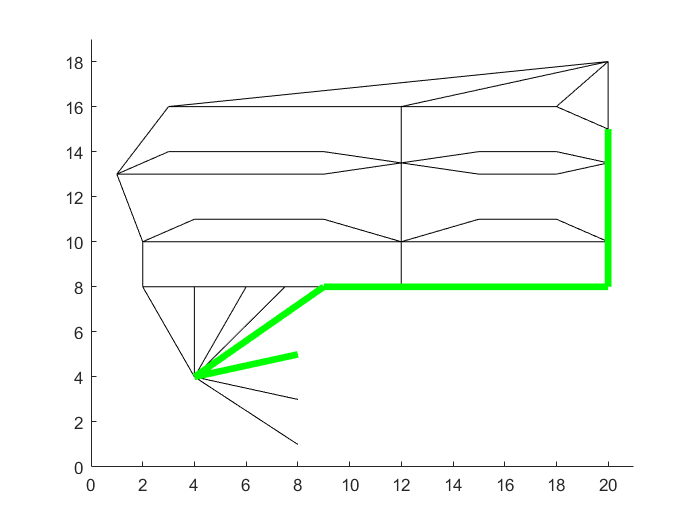


shortest_path_idx = G.shortestpath(start_node,end_node);
shortest_path_label = G.Nodes.Coordinates(shortest_path_idx);
shortest_path_edge = G.findedge(shortest_path_idx(1:end-1),shortest_path_idx(2:end));

for i = 1:numel(shortest_path_edge)
    line = G.Nodes.Coordinates(G.Edges.EndNodes(shortest_path_edge(i),:),:)';
    plot(line(1,:),line(2,:),'g','LineWidth',4);
end

Generate template VRP for python.

graph_template_all = "";
mini_template_all = "";

idx_start = EndNodes(1,:);
idx_stop = EndNodes(2,:);

for idx = 1:numel(G.Nodes.Coordinates(:,1))
    N = neighbors(G,idx);
    for j = N
        for k = 1:numel(j)
            if numel(j) == 1 || k == numel(j) 
                mini_template = "'%d': %.3f";                
            else
                mini_template = "'%d': %.3f,"; 
            end
            idx; N(k);
            
            start = find(idx_start == idx);
            stop = find(idx_stop == N(k));
            idx_target = intersect(start, stop);
            if isempty(idx_target) == 1
                start = find(idx_start == N(k));
                stop = find(idx_stop == idx);
                idx_target = intersect(start, stop);
            end
            
            mini_template = sprintf(mini_template,N(k),G.Edges.Weight(idx_target));
            mini_template_all = mini_template_all + mini_template;
        end
        graph_template = "'%d': {%s}";
        graph_template = sprintf(graph_template,idx,mini_template_all);
        if idx == numel(G.Nodes.Coordinates(:,1))
            graph_template_all = graph_template_all + newline + graph_template;
        else
            graph_template_all = graph_template_all + newline + graph_template + ', '; 
        end
        mini_template_all = "";
    end
end

graph_template_all

graph_template_all =     "
     '1': {'4': 5.000}, 
     '2': {'4': 4.123}, 
     '3': {'4': 4.123}, 
     '4': {'1': 5.000,'2': 4.123,'3': 4.123,'5': 4.472,'6': 4.000,'7': 4.472,'8': 5.315,'9': 6.403}, 
     '5': {'4': 4.472,'6': 2.000,'15': 2.000}, 
     '6': {'4': 4.000,'5': 2.000,'7': 2.000}, 
     '7': {'4': 4.472,'6': 2.000,'8': 1.500}, 
     '8': {'4': 5.315,'7': 1.500,'9': 1.500}, 
     '9': {'4': 6.403,'8': 1.500,'10': 3.000}, 
     '10': {'9': 3.000,'11': 3.000,'20': 2.000}, 
     '11': {'10': 3.000,'12': 1.500}, 
     '12': {'11': 1.500,'13': 1.500}, 
     '13': {'12': 1.500,'14': 2.000}, 
     '14': {'13': 2.000,'24': 2.000}, 
     '15': {'5': 2.000,'16': 2.000,'25': 2.236,'32': 3.162}, 
     '16': {'15': 2.000,'17': 2.000}, 
     '17': {'16': 2.000,'18': 1.500}, 
     '18': {'17': 1.500,'19': 1.500}, 
     '19': {'18': 1.500,'20': 3.000}, 
     '20': {'10': 2.000,'19': 3.000,'21': 3.000,'28': 3.162,'29': 3.162,'37': 3.500}, 
     '21': {'20': 3.000,'22': 1.500}, 
     '22'